# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 27-Aug-2020 16:16:38

## Setup the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 9);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Mfg", "Model", "Model_Year", "MPG", "Weight", "Cylinders", "Horsepower", "Acceleration", "Displacement"];
opts.VariableTypes = ["categorical", "string", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Model", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Mfg", "Model"], "EmptyFieldRule", "auto");

% Import the data
AutomobileData = readtable("E:\Harshit\HRS\Coursera\Exploratory Data Analysis\Exploratory Data Analysis\Module 2\Automobile Data.csv", opts)

AutomobileData = 406×9 table
       Mfg                       Model                     Model_Year    MPG    Weight    Cylinders    Horsepower    Acceleration    Displacement
    _________    ______________________________________    __________    ___    ______    _________    __________    ____________    ____________

    chevrolet    "chevrolet chevelle malibu           "        70         18     3504         8           130              12            307     
    buick        "buick skylark 320                   "        70         15     3693         8           165            11.5            350     
    plymouth     "plymouth satellite                  "        70         18    

## Clear temporary variables

clear opts

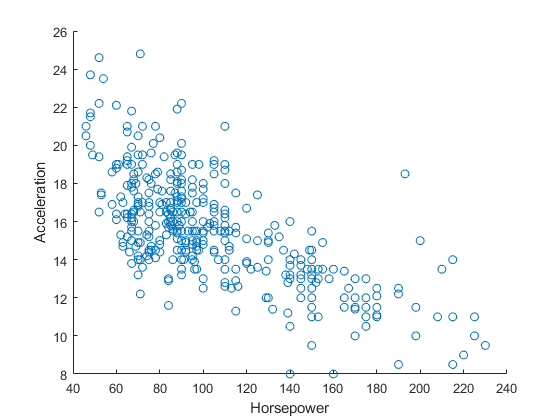

scatter(AutomobileData.Horsepower,AutomobileData.Acceleration)
xlabel('Horsepower')
ylabel('Acceleration')

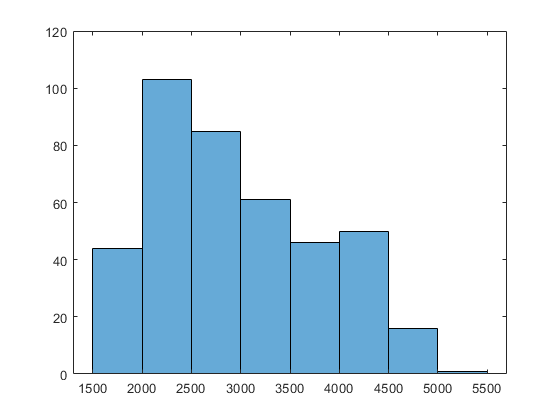

histogram(AutomobileData.Weight)

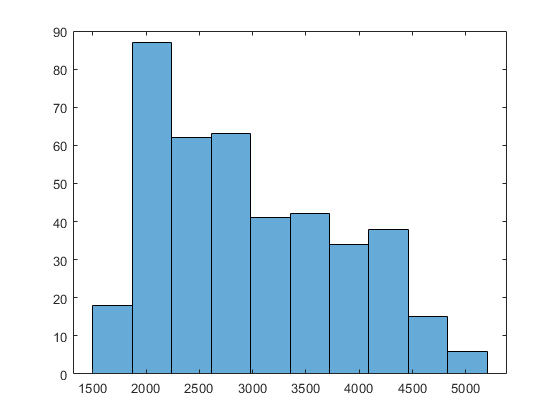

histogram(AutomobileData.Weight, 10)